clc
clear
RGB = readmatrix('thickness_all\thickness2rgb.csv');
t = RGB(:,1);
r_v = RGB(:,2)/256;
g_v = RGB(:,2)/256;
b_v = RGB(:,3)/256;
xyz_v = rgb2xyz([r_v,g_v,b_v]);

x = 1000;       %薄膜厚度/nm
n = 1.428;      %薄膜折射率
n0 = 1;         %空气折射率
ng = 3.836;     %硅片折射率
i = 0;          %折射角
lambda = 360:830;
x = 1:x;
delta = 4*pi*n*x'*cos(i)./lambda;
R = (n^2*(n0-ng)^2*cos(delta/2).^2+(n^2-n0*ng)^2*sin(delta/2).^2)./...
       (n^2*(n0+ng)^2*cos(delta/2).^2+(n^2+n0*ng)^2*sin(delta/2).^2);
cie = colorMatchFcn('1931_full');
XYZ = R*cie(:,2:4);
xyz_norm = normalize(XYZ,2,'norm',1);
rgb = xyz2rgb(xyz_norm);

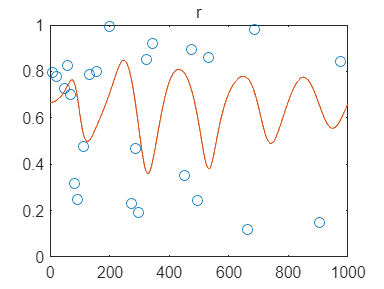

plot(t,r_v,'o')
title('r')
hold on
plot(rgb(:,1))
hold off

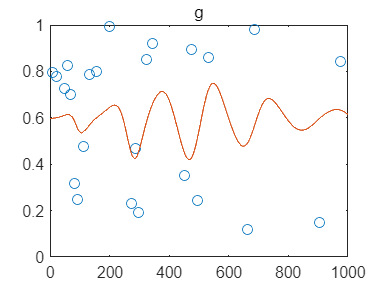

plot(t,g_v,'o')
title('g')
hold on
plot(rgb(:,2))
hold off

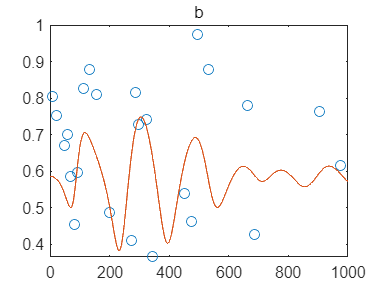

plot(t,b_v,'o')
title('b')
hold on
plot(rgb(:,3))
hold off